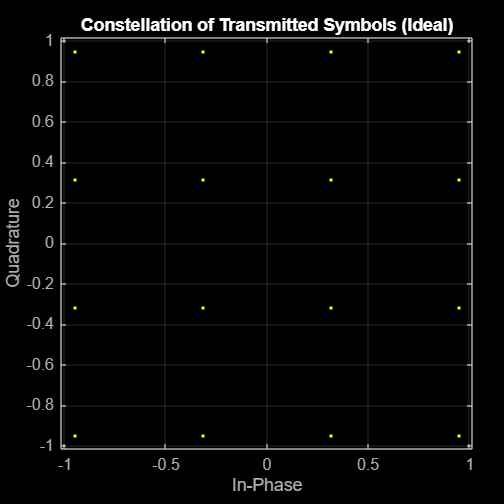

% Parameters
Nsubcarriers = 64;             % Number of subcarriers
cyclicPrefixLength = Nsubcarriers / 4;  % Length of cyclic prefix (1/4th of the OFDM symbol)
M = 16;                        % Modulation order (16-QAM)
Nbits = Nsubcarriers * 4;       % Number of bits (4 bits per subcarrier for 16-QAM)
SNR = 20;                      % Signal-to-Noise Ratio in dB (reduced for more visible effect)

% Channel properties (assuming a static channel for simplicity)
H = (randn(Nsubcarriers, 1) + 1i * randn(Nsubcarriers, 1)) / sqrt(2);  % Rayleigh fading channel

% Step 1: Data generation and mapping (16-QAM)
dataBits = randi([0 1], Nbits, 1);   % Random data bits
modulatedSymbols = qammod(bi2de(reshape(dataBits, [], log2(M))), M, 'UnitAveragePower', true); % 16-QAM modulation

% Plot ideal constellation before transmission
figure;
scatterplot(modulatedSymbols);
title('Constellation of Transmitted Symbols (Ideal)');
grid on;


% Step 2: Serial to parallel conversion
parallelData = reshape(modulatedSymbols, Nsubcarriers, []);  % Reshape to Nsubcarriers x (Nbits / Nsubcarriers)

% Step 3: IFFT (convert frequency domain to time domain) - Using custom IFFT function
timeDomainSymbols = ifft_function(parallelData, Nsubcarriers);  % Custom IFFT operation

% Step 4: Cyclic prefix addition
cyclicPrefix = timeDomainSymbols(end-cyclicPrefixLength+1:end, :);  % Take last part for CP
ofdmSymbolsWithCP = [cyclicPrefix; timeDomainSymbols];  % Append CP to each OFDM symbol

% Step 5: Parallel to serial conversion
serialData = ofdmSymbolsWithCP(:);  % Serialize the data for transmission

% Step 6: Transmission through AWGN channel
transmittedSignal = awgn(serialData .* H(:), SNR, 'measured');  % Add white Gaussian noise + effect of channel H

Arrays have incompatible sizes for this operation.

Related documentation


% OFDM Signal Reception
% Step 7: Serial to parallel conversion (reshape received data)
receivedParallelData = reshape(transmittedSignal, Nsubcarriers + cyclicPrefixLength, []);

% Step 8: Cyclic prefix removal
receivedSymbolsWithoutCP = receivedParallelData(cyclicPrefixLength+1:end, :);  % Remove cyclic prefix

% Step 9: FFT (convert time domain to frequency domain) - Using custom FFT function
receivedFrequencyDomainSymbols = fft_function(receivedSymbolsWithoutCP, Nsubcarriers);  % Custom FFT operation

% Equalization Methods:
% Zero-Forcing Equalization
zfEqualizedSymbols = zero_forcing_equalization(receivedFrequencyDomainSymbols, H);

% MMSE Equalization (with noise and signal power considerations)
noiseVariance = 10^(-SNR/10);  % Noise variance (based on SNR)
signalPower = 1;               % Assume unit signal power for simplicity
mmseEqualizedSymbols = mmse_equalization(receivedFrequencyDomainSymbols, H, noiseVariance, signalPower);

% Step 10: Demapping and BER Calculation for both ZF and MMSE

% Zero-Forcing demapping and BER
zfReceivedBits = reshape(de2bi(qamdemod(zfEqualizedSymbols(:), M, 'UnitAveragePower', true), log2(M)), [], 1);
numErrorsZF = sum(dataBits ~= zfReceivedBits);
berZF = numErrorsZF / length(dataBits);

% MMSE demapping and BER
mmseReceivedBits = reshape(de2bi(qamdemod(mmseEqualizedSymbols(:), M, 'UnitAveragePower', true), log2(M)), [], 1);
numErrorsMMSE = sum(dataBits ~= mmseReceivedBits);
berMMSE = numErrorsMMSE / length(dataBits);

% Plot constellation of received symbols after ZF equalization
figure;
scatterplot(zfEqualizedSymbols(:));
title('Constellation of Received Symbols (ZF Equalization)');
grid on;

% Plot constellation of received symbols after MMSE equalization
figure;
scatterplot(mmseEqualizedSymbols(:));
title('Constellation of Received Symbols (MMSE Equalization)');
grid on;

% Display results
disp(['Zero-Forcing Equalization - Number of bit errors: ', num2str(numErrorsZF)]);
disp(['Zero-Forcing Equalization - Bit Error Rate (BER): ', num2str(berZF)]);

disp(['MMSE Equalization - Number of bit errors: ', num2str(numErrorsMMSE)]);
disp(['MMSE Equalization - Bit Error Rate (BER): ', num2str(berMMSE)]);

%% Custom IFFT function
function timeDomainSymbols = ifft_function(parallelData, Nsubcarriers)
    [Nrows, Ncols] = size(parallelData);  % Get size of input matrix
    if Nrows ~= Nsubcarriers
        error('Number of rows in parallelData must match Nsubcarriers');
    end
    timeDomainSymbols = zeros(Nsubcarriers, Ncols);  % Initialize result matrix
    
    % IFFT calculation (Column-wise)
    for col = 1:Ncols
        X = parallelData(:, col);  % Select each column (frequency domain data)
        N = length(X);  % Number of points (should equal Nsubcarriers)
        x = zeros(N, 1);  % Initialize the time-domain result
        for n = 0:N-1
            for k = 0:N-1
                x(n+1) = x(n+1) + X(k+1) * exp(1i * 2 * pi * k * n / N);
            end
        end
        timeDomainSymbols(:, col) = x / N;  % Normalize by N and store result
    end
end

%% Custom FFT function
function receivedFrequencyDomainSymbols = fft_function(receivedSymbolsWithoutCP, Nsubcarriers)
    [Nrows, Ncols] = size(receivedSymbolsWithoutCP);  % Get size of input matrix
    if Nrows ~= Nsubcarriers
        error('Number of rows in receivedSymbolsWithoutCP must match Nsubcarriers');
    end
    receivedFrequencyDomainSymbols = zeros(Nsubcarriers, Ncols);  % Initialize result matrix
    
    % FFT calculation (Column-wise)
    for col = 1:Ncols
        x = receivedSymbolsWithoutCP(:, col);  % Select each column (time domain data)
        N = length(x);  % Number of points (should equal Nsubcarriers)
        X = zeros(N, 1);  % Initialize the frequency-domain result
        for k = 0:N-1
            for n = 0:N-1
                X(k+1) = X(k+1) + x(n+1) * exp(-1i * 2 * pi * k * n / N);
            end
        end
        receivedFrequencyDomainSymbols(:, col) = X;  % Store result
    end
end

%% Zero-Forcing Equalization
function equalizedSymbols = zero_forcing_equalization(receivedSymbols, H)
    % Zero-Forcing Equalization
    equalizedSymbols = receivedSymbols ./ H;
    equalizedSymbols(abs(H) < 1e-8) = 0;  % Avoid division by near-zero values
end

%% MMSE Equalization
function equalizedSymbols = mmse_equalization(receivedSymbols, H, noiseVariance, signalPower)
    % MMSE Equalization
    mmseFilter = conj(H) ./ (abs(H).^2 + noiseVariance / signalPower);
    equalizedSymbols = mmseFilter .* receivedSymbols;
end

